# Hands-on 02

## 1 Convolution

### 1.1 Toolbox - Simple convolution

The idea is to write functions that use certain input parameters like sampling frequency, duration, etc. and return a signal. the basic syntax will be like

Below some code snipplets that could be used to build such a function.

Let us use a square signal to show the idea:

% Some parameters
fs = ;      % sampling frequency in Hz
T_tot = ;    % total duration in s
T_0 = 10e-3;    % duration T0 in s
t = 1/fs:1/fs:T_tot;   % time vector

% Since we might not yet know how long our signal will be in total, we'll
% generate a vector corresponding to length T_0 and then pad to length
% T_tot

ramp_on = ones(1,fs*T_0);                           % make a vector of ones
ramp =[ramp_on zeros(1,fix((T_tot-T_0)*fs))];       % add some zeros to the end

% is the length correct? Should be fs*T_tot
% uncomment below
% length(ramp)

Now let's assume we have two signals that we want to convolve:

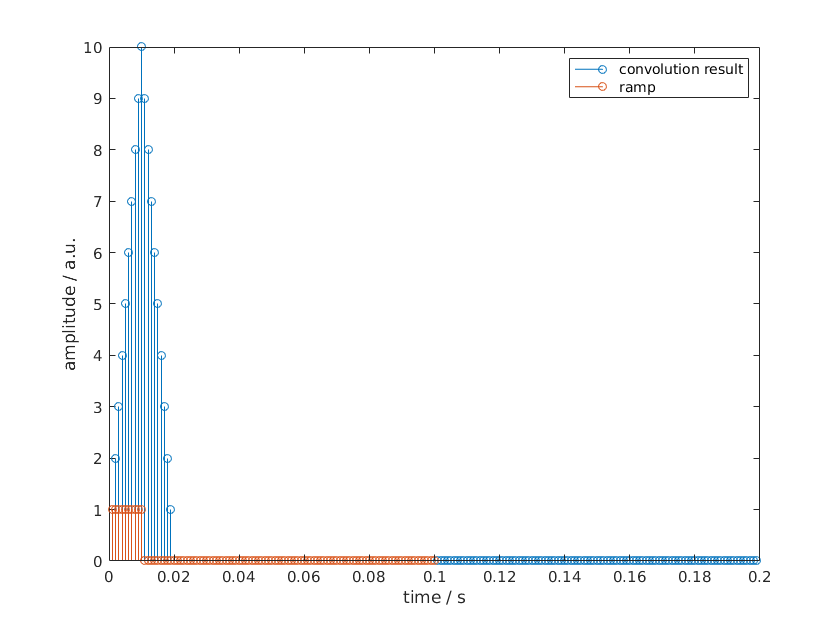

conv_result = conv(ramp, ramp);     % convolve the signals

t_ramp_ramp = (1:length(conv_result))/fs;   %can you make sense of this?

% plotting
figure('Name','Signal and convolution result')
stem(t_ramp_ramp,conv_result)
hold on;
stem(t,ramp);

xlabel('time / s')
ylabel('amplitude / a.u.')
legend({'convolution result','ramp'})


% calculate the length of the resulting signal

### 1.2 Filtering

Easy. Generate a ramp and a bunch of sinusoids. Then convolve.

clear all

% some parameters
fs = 10e3;      % sampling frequncy

% parameters of moving average
n_ma = 21;      % order of moving average
t_ma =          % make sure you get the interval correct!

Invalid expression. Check for missing or extra characters.


% parameters of sinusoids
f1 = 500;
f2 = 2200;
f3 = 4050;

T_sin = 1;
t_sin =         % make sure you match the time vector of the other signal

% generate the impulse response
h =             % you'll need n_ma+1 ones!

% plot it to see if all alignes!
stem(t_ma,h);
xlabel('time / s')
ylabel('amplitude / a.u.')

% generate the sinusoids
sin_500 = ...
sin_2200 = ...
sin_4050 = ...


% filtering


% plotting


## 2 Simple linear systems

### 2.1 Room reverberation

Here we just simulate a very (simplistic) IR of a room and convolve with some signals.

clear all;

% some parameters
fs = 44100;             % sampling frequency
alpha =              % reflection attentuation
tau =            % "echo" delay in s - try multiples!
delay_samples = fix(tau*fs)   % calculate the delay in samples

% generate the IR
h_ir = [1; zeros(delay_samples,1); alpha];


% let's load a .wav file and convolve it with our IR!
[y, fs_y] = audioread(['..', filesep, 'sounds', filesep ...
                'spoken_sentence.wav']);

% in case you'll load a stereo signal you might want to go MONO
y = y(:);       % we fist make it column vectors
y = y(:,1);     % and then we only use the first column

% Now we need to see if the sampling frequencies match! If not, sample to
% the fs of the audio signal
if (fs~=fs_y)
    h_ir_resample = resample(h_ir, fs_y, fs);
    out = conv(h_ir_resample, y);
else
    out = conv(h_ir, y);
end
            
% normalize the amplitude that you don't blow your ears
out = out/max(out)*.5;

% uncomment below to listen to the sound. HINT:
% >> clear sound
% (in the command line) will interrupt the sound if it sound too crappy

% sound(out, fs_y)




### 2.2 Putting sounds into different places

Tha is simple. Load the IRs from the files (remember the sampling frequency), possibly check if you have multiple channels (leading to a matrix, not a vector). Then load a signal you want to convolve, match the sampling frequencies and have fun!